# HexaMotor — Sub-Demo: Step Response vs. Frequency Response Identification

*Open-loop velocity identification on *`HexaMotor_System_Identification_V02.slx`*, following the "Velocity Control V02" manual (sections 1.4, 1.5, 3.3, 3.4).*

The same first-order motor $G(s) = \frac{K}{\tau s + 1}$ is identified two ways, and the results are compared with each other and with the closed-loop model from `HexaMotor_SysID_Demo`:

- **Step response (bump test)** — one 0 → 7 V step; fast and simple.

- **Frequency response** — 7 V sine inputs at several frequencies; slower, but it separates the motor from the known velocity filter.

## 0. Demo settings

- **Virtual motor** — the experiments run on the built-in nonlinear motor emulator (no hardware needed).

- **Hardware** — the experiments run on the HexaMotor (Monitor & Tune / external mode); the Simulink model and its Scope open and stream live during each run.

runMode = "sim";
stepV = 7;                        % step size and sine amplitude [V]
wList = [2 4 7 10 15 20 30];      % sine test frequencies [rad/s] (manual: at least 7 points in 0..30 rad/s)

fs = 200; Ts = 1/fs;
sampleRate = Ts;                  % used by the Simulink model (a sample TIME)
siModel = "HexaMotor_System_Identification_V02";
s = tf('s');
LPF = 1/(0.05*s + 1);             % velocity-measurement filter in the model (Filtered Derivative, T = 0.05 s)
if runMode == "hw", measLabel = "Measured"; else, measLabel = "Emulated"; end
cS = [0.85 0.33 0.10]; cF = [0.00 0.30 0.75]; cD = [0.47 0.67 0.19];

## 1. Two ways to the same two numbers

**Step response.** For a step of size $A$, the first-order model responds as


$$\omega(t) = KA\left(1 - e^{-t/\tau}\right), \qquad K = \frac{\Delta\omega_{\mathrm{ss}}}{\Delta V}, \qquad \omega(\tau) = 0.632\,KA$$


**Frequency response.** For a sine input of frequency $\omega$, the output is a sine of the same frequency with


$$|G(j\omega)| = \frac{K}{\sqrt{\tau^2\omega^2 + 1}}, \qquad \varphi(\omega) = -\tan^{-1}(\tau\omega), \qquad \tau = \frac{1}{\omega_b}\ \ \mathrm{where}\ \ |G(j\omega_b)| = \frac{K}{\sqrt{2}}$$


Both measurements see the motor **through** the 0.05 s velocity filter. The frequency method can divide the filter out exactly, point by point. The 63.2 % step rule cannot, so its $\tau$ absorbs part of the filter lag.

## 2. Experiment A — step response (bump test)

Manual Switch on **Step**, 0 → 7 V at $t$ = 1 s, 4 s run.

 
if runMode == "hw"
    load_system(siModel);
    set_param(siModel, FixedStep=num2str(Ts));
    set_param(siModel + "/Manual Switch1", sw="1");            % "1" = upper input = Step
    set_param(siModel + "/Step", Time="1", InitialValue="0", FinalValue=num2str(stepV));
    stepData = runOnHexaMotor(siModel, 4);
else
    stepData = virtualOpenLoop("step", Ts, 4, stepV, 0);
end
tA = stepData.time; uA = stepData.signals.values(:,1); yA = stepData.signals.values(:,2);
y0 = mean(yA(tA > 0.5 & tA < 1));
yss = mean(yA(tA > 3 & tA < 4));
Kstep = (yss - y0)/stepV;
i63 = find(tA > 1 & yA >= y0 + 0.632*(yss - y0), 1);
tauStep = tA(i63) - 1;
Gstep = Kstep/(tauStep*s + 1);
fprintf("Step method:       K = %.3f rad/s/V, tau = %.4f s\n", Kstep, tauStep);

Step method:       K = 2.441 rad/s/V, tau = 0.1300 s


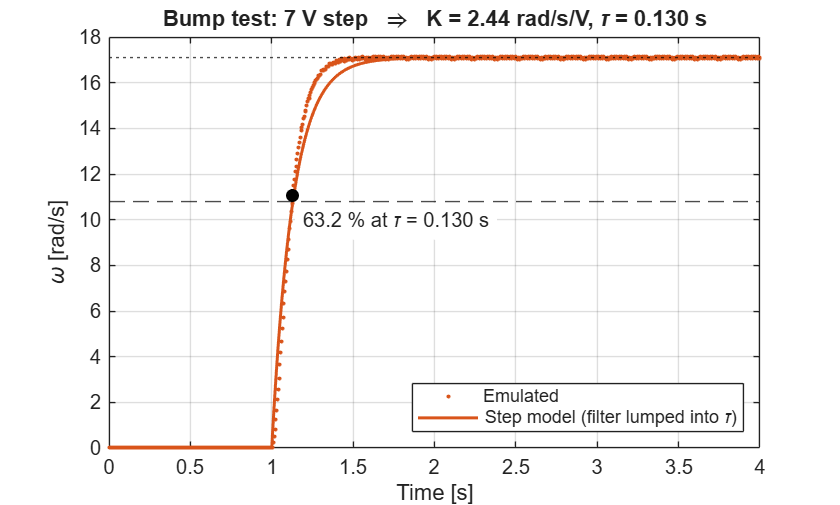


figure
plot(tA, yA, ".", MarkerSize=6, Color=cS); hold on
plot(tA, lsim(Gstep, uA, tA), "-", LineWidth=1.5, Color=cS)
plot(tA(i63), yA(i63), "ko", MarkerFaceColor="k")
yline(yss, "k:"); yline(y0 + 0.632*(yss - y0), "k--"); hold off
text(tA(i63) + 0.05, yA(i63) - 0.6, sprintf("63.2 %% at \\tau = %.3f s", tauStep), VerticalAlignment="top", BackgroundColor="w")
grid on; xlabel("Time [s]"); ylabel("\omega [rad/s]")
legend(measLabel, "Step model (filter lumped into \tau)", Location="southeast")
title(sprintf("Bump test: %g V step  \\Rightarrow  K = %.2f rad/s/V, \\tau = %.3f s", stepV, Kstep, tauStep))

## 3. Experiment B — frequency response

Manual Switch on **Sine Wave**, 7 V amplitude, one run per frequency. Each run lasts long enough to settle and record at least 3 periods. Gain and phase come from a least-squares sine fit to the steady-state part of input and output, so no manual reading of peaks and time delays is needed. In hardware mode this is one run per frequency.

 
Hm = zeros(size(wList));
for i = 1:numel(wList)
    w = wList(i);
    stopT = max(4, 1.5 + 4*2*pi/w);
    if runMode == "hw"
        load_system(siModel);
        set_param(siModel + "/Manual Switch1", sw="0");        % "0" = lower input = Sine Wave
        set_param(siModel + "/Sine Wave" + newline + "Function", Amplitude=num2str(stepV), Frequency=num2str(w));
        d = runOnHexaMotor(siModel, stopT);
    else
        d = virtualOpenLoop("sine", Ts, stopT, stepV, w);
    end
    keep = d.time > stopT - 3*2*pi/w;                         % last 3 periods
    Hm(i) = sinePhasor(d.time(keep), d.signals.values(keep,2), w) / sinePhasor(d.time(keep), d.signals.values(keep,1), w);
    fprintf("w = %4.1f rad/s:  gain = %.3f rad/s/V (%5.2f dB), phase = %6.1f deg\n", w, abs(Hm(i)), 20*log10(abs(Hm(i))), rad2deg(angle(Hm(i))));
end

w =  2.0 rad/s:  gain = 2.417 rad/s/V ( 7.66 dB), phase =  -13.4 deg
w =  4.0 rad/s:  gain = 2.321 rad/s/V ( 7.31 dB), phase =  -26.4 deg
w =  7.0 rad/s:  gain = 2.095 rad/s/V ( 6.42 dB), phase =  -44.5 deg
w = 10.0 rad/s:  gain = 1.825 rad/s/V ( 5.22 dB), phase =  -60.4 deg
w = 15.0 rad/s:  gain = 1.393 rad/s/V ( 2.88 dB), phase =  -82.2 deg
w = 20.0 rad/s:  gain = 1.050 rad/s/V ( 0.42 dB), phase =  -98.8 deg
w = 30.0 rad/s:  gain = 0.617 rad/s/V (-4.19 dB), phase = -121.5 deg


% the filter is known exactly -> divide it out, then fit a first-order model (as in the manual, via idfrd + tfest)
Hmotor = Hm ./ squeeze(freqresp(LPF, wList)).';
Ffit = tfest(idfrd(reshape(Hmotor, 1, 1, []), wList, 0), 1, 0);
denF = Ffit.Denominator;                                   % [a1 a0] -> K/(tau s + 1)
tauFreq = denF(1)/denF(2);
Kfreq = Ffit.Numerator(end)/denF(2);
Gfreq = Kfreq/(tauFreq*s + 1);
fprintf("Frequency method:  K = %.3f rad/s/V, tau = %.4f s\n", Kfreq, tauFreq);

Frequency method:  K = 2.459 rad/s/V, tau = 0.0671 s


## 4. Comparison

The closed-loop model from `HexaMotor_SysID_Demo` (`HexaMotorModel`, from the workspace or `HexaMotorModel.mat`) is included when it is available.

models = {"Step response (63.2 % rule)", Kstep, tauStep; "Frequency response (filter removed)", Kfreq, tauFreq};
if ~exist("HexaMotorModel", "var") && isfile("HexaMotorModel.mat"), load("HexaMotorModel.mat", "HexaMotorModel"); end
if exist("HexaMotorModel", "var")
    models(end+1, :) = {"Closed-loop chirp (SysID demo)", HexaMotorModel.km, HexaMotorModel.tau};
end
cmp = cell2table(models, VariableNames=["Method" "K_rad_s_per_V" "tau_s"]);
cmp.Bandwidth_Hz = 1./(2*pi*cmp.tau_s);
cmp.Method = string(cmp.Method);
disp(cmp)

                   Method                    K_rad_s_per_V     tau_s      Bandwidth_Hz
    _____________________________________    _____________    ________    ____________

    "Step response (63.2 % rule)"               2.4412            0.13       1.2243   
    "Frequency response (filter removed)"       2.4589        0.067093       2.3722   
    "Closed-loop chirp (SysID demo)"            2.4942        0.081027       1.9642   



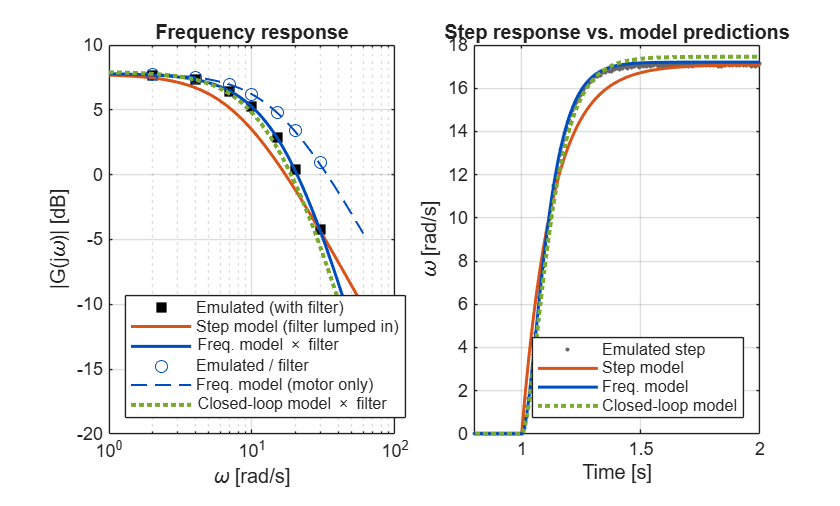


wB = logspace(log10(1), log10(60), 300);
figure
tiledlayout(1, 2, TileSpacing="compact")
nexttile
magdb = @(G) 20*log10(squeeze(abs(freqresp(G, wB))));
semilogx(wList, 20*log10(abs(Hm)), "ks", MarkerFaceColor="k", MarkerSize=6); hold on
semilogx(wB, magdb(Gstep), "-", Color=cS, LineWidth=1.5)
semilogx(wB, magdb(Gfreq*LPF), "-", Color=cF, LineWidth=1.5)
semilogx(wList, 20*log10(abs(Hmotor)), "o", Color=cF, MarkerSize=6)
semilogx(wB, magdb(Gfreq), "--", Color=cF, LineWidth=1)
if exist("HexaMotorModel", "var"), semilogx(wB, magdb(HexaMotorModel.km/(HexaMotorModel.tau*s + 1)*LPF), ":", Color=cD, LineWidth=2); end
hold off; grid on; xlabel("\omega [rad/s]"); ylabel("|G(j\omega)| [dB]")
leg = [measLabel + " (with filter)", "Step model (filter lumped in)", "Freq. model \times filter", measLabel + " / filter", "Freq. model (motor only)"];
if exist("HexaMotorModel", "var"), leg(end+1) = "Closed-loop model \times filter"; end
legend(leg, Location="southwest")
title("Frequency response")
nexttile
plot(tA, yA, ".", MarkerSize=6, Color=[0.4 0.4 0.4]); hold on
plot(tA, lsim(Gstep, uA, tA), "-", Color=cS, LineWidth=1.5)
plot(tA, lsim(Gfreq*LPF, uA, tA), "-", Color=cF, LineWidth=1.5)
if exist("HexaMotorModel", "var"), plot(tA, lsim(HexaMotorModel.km/(HexaMotorModel.tau*s + 1)*LPF, uA, tA), ":", Color=cD, LineWidth=2); end
hold off; grid on; xlim([0.8 2]); xlabel("Time [s]"); ylabel("\omega [rad/s]")
leg = [measLabel + " step", "Step model", "Freq. model"];
if exist("HexaMotorModel", "var"), leg(end+1) = "Closed-loop model"; end
legend(leg, Location="southeast")
title("Step response vs. model predictions")

**Take-aways**

- The step test is fast (one run) and gives $K$ reliably. Its model matches the measured step well, but only because the 0.05 s filter lag is lumped into $\tau$. So it overestimates the motor's own time constant, and its Bode curve rolls off too early.

- The frequency test takes one run per frequency. Because the filter is known, it can be removed exactly, which gives the motor's own $\tau$.

- The closed-loop chirp in `HexaMotor_SysID_Demo` works on the position signal, which is not filtered, and needs only one run. That is why it is the model used for the controller designs.

## Local functions

function P = sinePhasor(t, x, w)
% Least-squares fit x ~ a sin(wt) + b cos(wt) + c  ->  phasor a + jb (amplitude and phase of the sine).
c = [sin(w*t) cos(w*t) ones(size(t))] \ x;
P = c(1) + 1j*c(2);
end

function showLiveView(mdl, stopTime)
% Open the model diagram and its Scope so the audience sees the running model and the live
% external-mode response; the Scope time span covers the whole run.
open_system(mdl);
scopes = find_system(mdl, SearchDepth=1, BlockType="Scope");
for i = 1:numel(scopes)
    cfg = get_param(scopes{i}, "ScopeConfiguration");
    cfg.TimeSpan = num2str(stopTime);
    cfg.OpenAtSimulationStart = true;
    cfg.Visible = true;
end
drawnow
end

function sd = runOnHexaMotor(mdl, stopTime)
% Build, deploy and run a model on the HexaMotor in external mode (the "Monitor & Tune" button),
% wait for it to stop and return the Scope's logged ScopeData.
mdl = char(mdl);
set_param(mdl, StopTime=num2str(stopTime), SimulationMode="external");
showLiveView(mdl, stopTime);                      % model diagram + live Scope during the run
evalin("base", "clear ScopeData");
fprintf("Building, deploying and running %s on the HexaMotor ...\n", mdl);
set_param(mdl, SimulationCommand="start");
t0 = tic;
while toc(t0) < 600 + 3*stopTime
    pause(0.5); drawnow
    if strcmp(get_param(mdl, "SimulationStatus"), "stopped") && evalin("base", "exist('ScopeData','var')")
        break
    end
end
if ~evalin("base", "exist('ScopeData','var')")
    error("No ScopeData received from %s. Check the USB cable, power switch and the Scope logging settings.", mdl);
end
sd = evalin("base", "ScopeData");
fprintf("Done: %d samples recorded.\n", numel(sd.time));
end

function sd = virtualOpenLoop(refType, Ts, stopTime, amp, w)
% Nonlinear stand-in for the HexaMotor in open loop (voltage in, filtered velocity out).
kmT = 2.42; tauT = 0.0705;        % true first-order motor [rad/s/V], [s]
Vstick = 0.32; Vcoul = 0.28;      % static / kinetic friction, voltage-equivalent [V]
Vcomp = 0.35;                     % friction feed-forward in the model [V]
enc = 2*pi/979.62;                % encoder resolution at the gearbox output [rad]
Tf = 0.05;                        % Filtered Derivative time constant [s]
t = (0:round(stopTime/Ts))'*Ts;
if refType == "step", u = amp*(t >= 1); else, u = amp*sin(w*t); end
nSub = 20; dt = Ts/nSub;
theta = 0; wm = 0; velF = 0; thPrev = 0;
y = zeros(size(t));
for k = 1:numel(t)
    thq = enc*round(theta/enc);
    velF = velF + Ts/Tf*((thq - thPrev)/Ts - velF);
    thPrev = thq;
    y(k) = velF;
    v = u(k) + Vcomp*sign(u(k));
    v = round(min(max(v, -12), 12)/12*255)*12/255;   % 8-bit PWM, 12 V supply
    for j = 1:nSub
        if wm == 0 && abs(v) <= Vstick, continue, end
        dir = sign(wm); if dir == 0, dir = sign(v); end
        wNew = wm + dt*(kmT*(v - Vcoul*dir) - wm)/tauT;
        if wm ~= 0 && sign(wNew) ~= sign(wm) && abs(v) <= Vstick, wNew = 0; end
        theta = theta + dt*(wm + wNew)/2;
        wm = wNew;
    end
end
sd.time = t;
sd.signals.values = [u y];
end